# Nagel Schreckenberg - periodic street

## initialization

[u,p] = myInit("plot",1);

## time evolution

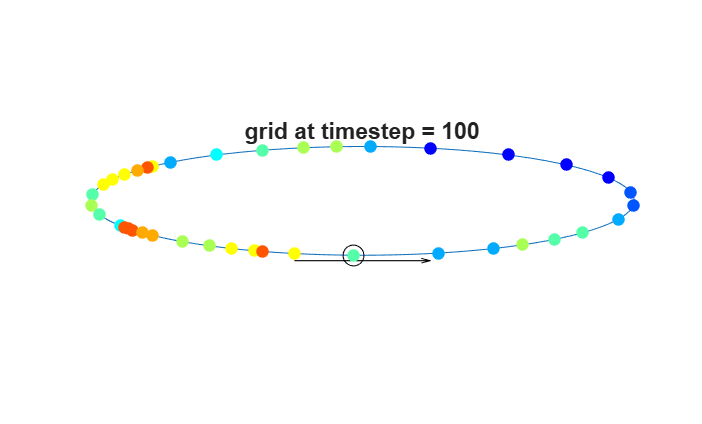

t = 1;
G = u;
h = myDrawnow(u,p,t,[]);
while t < p.tend
    u = myUpdate(u,p);
    t = t+1;
    myDrawnow(u,p,t,h);
    G(end+1,:) = u;
end

## sanity check

s = sum(~isnan(G),2);
if all(s==s(1))
    fprintf('Number of cars = %u\n',s(1));
else
    error('number of cars must not change'); 
end

Number of cars = 40


## plot time vs street

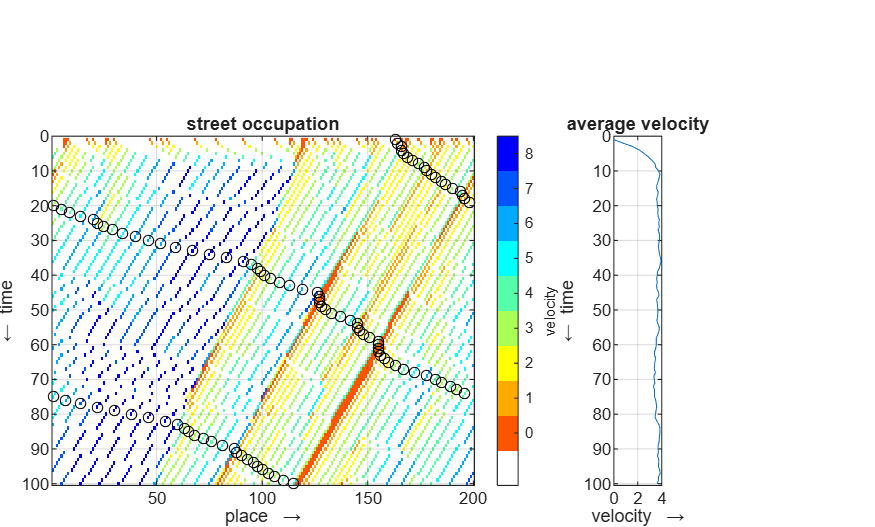

TimeSpacePlot(G,p);